# Load resources

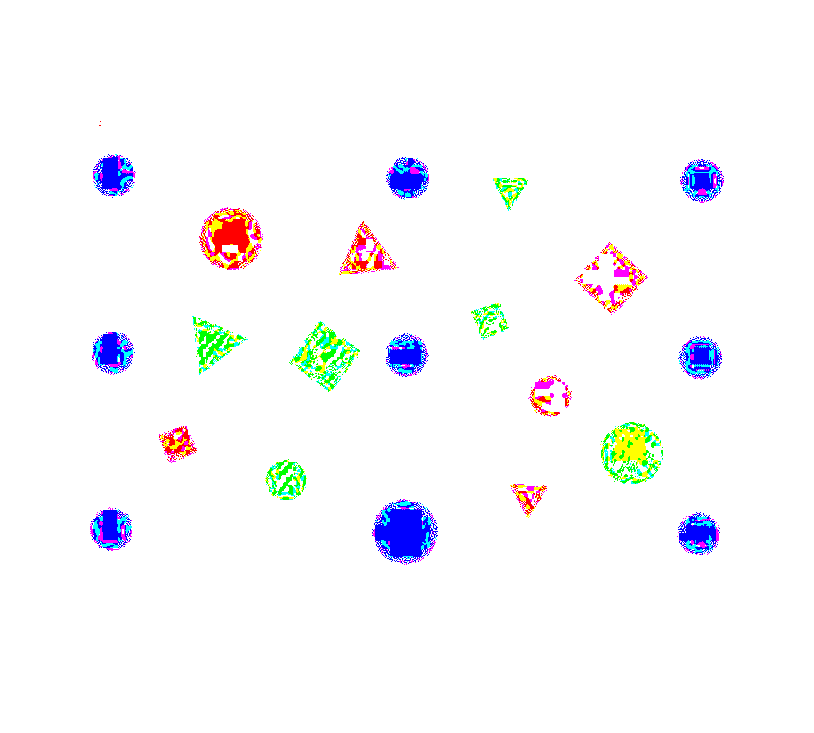

clear All; close all;
capture = double(imread("capture.jpg"));
init_image = double(imread("init_image2.jpg"));
dest_image = double(imread("init_image3.jpg"));
imshow(capture)

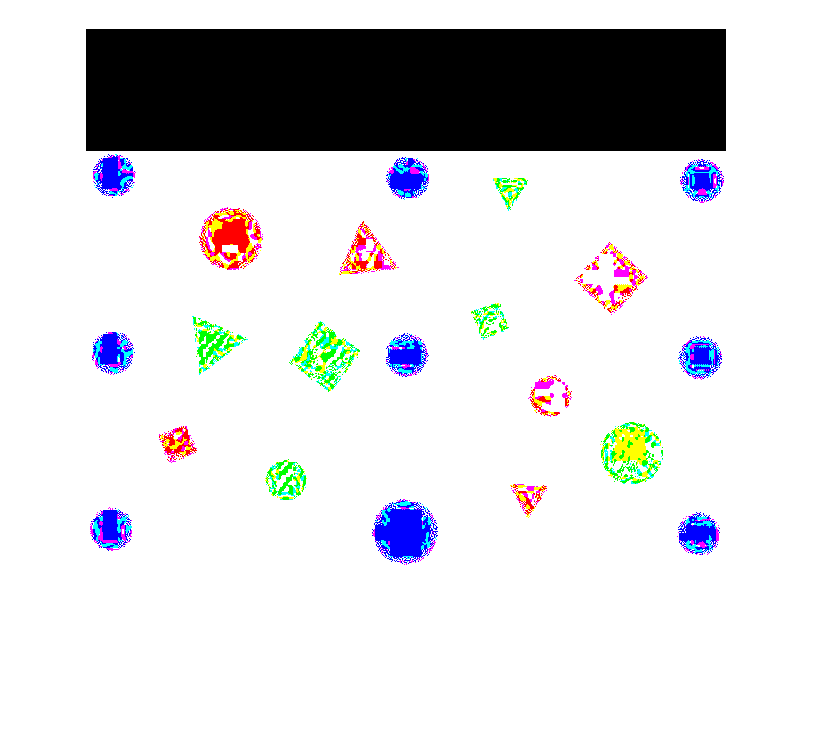


% % Zero the text part
% plainImage = plainSpace;
% plainImage(:,3015:end,:) = 0;
% imshow(plainImage)

% Zero the text part
plainImage = capture;
plainImage(1:122,:,:) = 0;
% plainImage = plainSpace(:,1:3015,:); %double(plainspace(60:4619,129:2995,:));
imshow(plainImage)

## Run

% % Get colour plains
% red = plainImage(:,:,1);
% green = plainImage(:,:,2);
% blue = plainImage(:,:,3);
% imshow(blue)
% 
% % Get blue circles
% blueCircles = imclose(blue./(red+green+blue) > 0.5, ones(4,4));
% figure; imshow(blueCircles); title("blueCircles");
% 
% % get red shapes
% % Old method to filter noise: redBinary = medfilt2(red./(red+green+blue) > 0.45, [3,3]);
% redBinary = imclose(red./(red+green+blue) > 0.5, ones(4,4));
% figure; imshow(redBinary); title("redBinary");
% 
% % Get green shapes
% green = green./(red+green+blue) > 0.5;
% greenBinary = imclose(green, ones(5,5));
% figure; imshow(greenBinary); title("greenBinary"); 

% 
% % Get data from sheet
% % Get blue centroids
% blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
% imshow(blueCircles)
% hold on
% plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
% hold off
% 
% % Get red centroids
% redStats = regionprops("table",redBinary,"Centroid","Area","Circularity");
% imshow(redBinary)
% hold on
% plot(redStats.Centroid(:,1),redStats.Centroid(:,2),"b*")
% hold off
% 
% % Get green centroids
% greenStats = regionprops("table",greenBinary,"Centroid","Area","Circularity");
% imshow(greenBinary)
% hold on
% plot(greenStats.Centroid(:,1),greenStats.Centroid(:,2),"b*")
% hold off
%get image colour data
[redStats,blueStats,greenStats] = extractColor(plainImage)

redStats = 61×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

      575    14.831     161.7      0.16076  
       77    3.9221    309.56       0.6337  
      426    22.878    345.05      0.13723  
      951    63.073    522.37     0.036083  
    67502    321.37    587.53      0.30416  
        5      12.2     304.6       2.5519  
       11    17.364    123.91       1.7887  
      375    32.776     295.8      0.41675  
      221    24.312    471.18      0.84869  
      382    54.906    139.38      0.26022  
       44    46.045    484.41      0.32029  
       16    48.625    161.69      0.90832  
      155    58.277    327.54      0.72976  
     1654    92.038    413.73      0.23153  
     4002    126.92    313.06      0.37512  
     2932    148.61    210.35      0.33969  


blueStats = 101×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    2753    31.472    149.03      0.55586  
      12         2     175.5       1.6936  
    2704    27.679    323.78      0.36878  
    2419    24.804    501.47      0.51998  
      19    46.895    289.58       1.4778  
       9        48       528       2.0235  
      35    63.971    325.34      0.73447  
    1340    90.574    413.07      0.16076  
       3        81    448.67       1.7894  
       2      83.5     415.5       3.1784  
      35    91.257    447.63      0.78509  
     522    123.29     287.8      0.08283  
     378    102.12    328.68      0.17358  
      33    99.091    417.27       0.6134  
    1439    157.67    204.22     0.062694  
     114    127.44    348.47      0.62891  


greenStats = 255×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    3545    387.92    297.95         Inf   
    1565    315.51     310.9      499.14   
    1159    317.46    302.09         Inf   
     927    321.02    314.05         Inf   
     643     318.1     303.8      525.83   
     477    303.49    316.94         Inf   
     462    331.05    308.67         Inf   
     361    338.85    318.55      1180.9   
     286    337.78    324.87         Inf   
     289    329.43    316.64         Inf   
     249     362.9    323.98         Inf   
     216    349.84    322.24         Inf   
     208    309.31    315.74         Inf   
     166    328.52    322.66         Inf   
     145    326.41    337.01         Inf   
     149    334.62    305.63         Inf   



% create single array of sheet data
% tasksheetBlue = data(blueStats,"blue",1600)
tasksheetRed = data(redStats,"red",1600)

tasksheetRed = 44×6 string array
    "red"    "Triangle"    "14.8313"     "161.7043"    "575"      "False"
    "red"    "Triangle"    "3.9221"      "309.5584"    "77"       "False"
    "red"    "Triangle"    "22.8779"     "345.054"     "426"      "False"
    "red"    "Triangle"    "63.0726"     "522.3659"    "951"      "False"
    "red"    "Triangle"    "321.3731"    "587.5251"    "67502"    "True" 
    "red"    "Triangle"    "32.776"      "295.8027"    "375"      "False"
    "red"    "Square"      "24.3122"     "471.181"     "221"      "False"
    "red"    "Triangle"    "54.9058"     "139.3848"    "382"      "False"
    "red"    "Triangle"    "46.0455"     "484.4091"    "44"       "False"
    "red"    "Square"      "58.2774"     "327.5419"    "155"      "False"
    "red"    "Triangle"    "92.0381"     "413.7346"    "1654"     "True" 
    "red"    "Triangle"    "126.9175"    "313.0645"    "4002"     "True" 
    "red"    "Triangle"    "148.6136"    "210.3503"    "2932"     "True" 
    "

tasksheetGreen = data(greenStats,"green",1600)

tasksheetGreen = 142×6 string array
    "green"    "Circle"    "387.9193"    "297.9475"    "3545"    "True" 
    "green"    "Circle"    "315.5144"    "310.9035"    "1565"    "False"
    "green"    "Circle"    "317.459"     "302.088"     "1159"    "False"
    "green"    "Circle"    "321.0194"    "314.0496"    "927"     "False"
    "green"    "Circle"    "318.1042"    "303.804"     "643"     "False"
    "green"    "Circle"    "303.4927"    "316.9371"    "477"     "False"
    "green"    "Circle"    "331.0455"    "308.671"     "462"     "False"
    "green"    "Circle"    "338.8476"    "318.5457"    "361"     "False"
    "green"    "Circle"    "337.7832"    "324.8671"    "286"     "False"
    "green"    "Circle"    "329.4325"    "316.6436"    "289"     "False"
    "green"    "Circle"    "362.8996"    "323.9759"    "249"     "False"
    "green"    "Circle"    "349.838"     "322.2407"    "216"     "False"
    "green"    "Circle"    "309.3125"    "315.7404"    "208"     "False"
    "green"    

% combine them together
% tasksheet = cat(1,tasksheetBlue,tasksheetGreen)
tasksheet = cat(1,tasksheetRed,tasksheetGreen)

tasksheet = 186×6 string array
    "red"    "Triangle"    "14.8313"     "161.7043"    "575"      "False"
    "red"    "Triangle"    "3.9221"      "309.5584"    "77"       "False"
    "red"    "Triangle"    "22.8779"     "345.054"     "426"      "False"
    "red"    "Triangle"    "63.0726"     "522.3659"    "951"      "False"
    "red"    "Triangle"    "321.3731"    "587.5251"    "67502"    "True" 
    "red"    "Triangle"    "32.776"      "295.8027"    "375"      "False"
    "red"    "Square"      "24.3122"     "471.181"     "221"      "False"
    "red"    "Triangle"    "54.9058"     "139.3848"    "382"      "False"
    "red"    "Triangle"    "46.0455"     "484.4091"    "44"       "False"
    "red"    "Square"      "58.2774"     "327.5419"    "155"      "False"
    "red"    "Triangle"    "92.0381"     "413.7346"    "1654"     "True" 
    "red"    "Triangle"    "126.9175"    "313.0645"    "4002"     "True" 
    "red"    "Triangle"    "148.6136"    "210.3503"    "2932"     "True" 
    "re

%dest_image and init_image data
[redInitStats,blueInitStats,greenInitStats] = extractColor(init_image)

redInitStats = 32×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

     8386     196.9    236.23     0.026256  
        1       175       205          Inf  
       15    257.87     191.6       1.4451  
       11    271.55    153.27       1.1759  
        3       274       216       2.4533  
     2207    318.83    265.08      0.20197  
       19    318.42    231.11       1.4778  
        5       364       359       1.0222  
    23683    515.31    268.26      0.36639  
       10     433.2     257.5       1.8937  
        8     449.5     230.5       1.7987  
       18    497.67       146       1.5537  
        4     607.5     279.5       3.9751  
       19    622.89    335.42       1.4778  
       19    623.42    306.11       1.4778  
    12752    805.48    277.25      0.01978  


blueInitStats = 158×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

      19    66.158    351.37       1.3518  
       5      66.4     336.6       1.2775  
    5767    228.54    346.14       0.1115  
      53    82.717    336.25      0.45094  
     161    86.839    318.27      0.26159  
      11    81.909    305.64       1.7887  
    1434     224.7       367     0.056006  
     154    103.65     309.1      0.31571  
      16      97.5     273.5       1.5482  
      35    97.314    293.69      0.83811  
       1        97       330          Inf  
     356    113.61    276.69      0.14833  
      18    107.17    319.28       1.5242  
       7    124.71    287.29       1.2965  
     175    133.91    257.35      0.47936  
     363    143.59    223.62      0.13745  


greenInitStats = 255×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    2964    572.16    260.82      9695.6   
    2984    538.38    269.21         Inf   
    2118    517.98    267.52         Inf   
    1606    503.78    272.23      368.35   
    1146    489.19    271.73         Inf   
     705    562.92    255.82         Inf   
     850    458.74    284.34      1350.8   
     743    436.56    282.34         Inf   
     396    548.68    246.57         Inf   
     324    550.94     251.9         Inf   
     284    572.94    259.96         Inf   
     256    541.42     248.3      152.69   
     213    566.05    250.86         Inf   
     203    571.73    268.14         Inf   
     178    506.31    243.59      582.26   
     167     521.7     246.4         Inf   


[redDestStats,blueDestStats,greenDestStats] = extractColor(dest_image)

redDestStats = 7×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

     7250    224.68    251.05     0.077075  
       80    350.71    147.35      0.37497  
    27612    510.82    262.64      0.78791  
    47225    797.73     256.7       0.3429  
        9    641.89       343       1.0877  
       17    863.41    162.12       1.6378  
       14     879.5    193.71       1.7226  


blueDestStats = 73×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

    14047    236.92    245.03     0.029232  
       18    338.83    129.33       1.4202  
       14    433.14    185.64       1.4411  
        2     432.5       321       6.5423  
        4    432.75       328       2.3859  
        8    433.12    335.88       2.1544  
       28    436.39    177.96       1.2965  
       13       443    182.85       1.5995  
      103    493.18    179.01      0.03497  
      289    520.34    183.94     0.042753  
      840    589.38    251.05      0.11237  
       12    586.08    335.42       1.4765  
       11    586.82    327.09       1.3782  
       14       592    333.29      0.75648  
     1933    788.05    346.13     0.042539  
       20    658.55    289.65        1.423  


greenDestStats = 255×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    3035    265.78    215.87          Inf  
    1561    219.73    304.23      0.10737  
     718    181.96    261.99     0.051166  
     479    167.97    211.58          Inf  
     690    182.16    330.47          Inf  
     296    230.65    351.38       388.81  
     336    277.85    226.95          Inf  
     336    224.27    293.55       1099.1  
     451    107.39    260.98     0.030421  
      20     148.8    239.35       2.3745  
     214    330.13     260.4       127.64  
       7    271.86    247.71          Inf  
       5     195.6       192          Inf  
       3    258.67    296.33          Inf  
       7    205.71    242.29          Inf  
      25    282.56       283          Inf  



%create single array of dest data
inits = data(redInitStats,"red",37260);
inits2 = data(greenInitStats,"green",37260);
%combine 
inits = cat(1,inits,inits2)

inits = 91×6 string array
    "red"      "Triangle"    "196.8972"    "236.2266"    "8386"     "False"
    "red"      "Triangle"    "318.826"     "265.0847"    "2207"     "False"
    "red"      "Triangle"    "515.3057"    "268.2555"    "23683"    "False"
    "red"      "Triangle"    "805.48"      "277.2499"    "12752"    "False"
    "red"      "Circle"      "671.1176"    "243.5588"    "34"       "False"
    "red"      "Circle"      "744.8491"    "414.5094"    "53"       "False"
    "green"    "Circle"      "572.1576"    "260.8235"    "2964"     "False"
    "green"    "Circle"      "538.38"      "269.2125"    "2984"     "False"
    "green"    "Circle"      "517.9783"    "267.5165"    "2118"     "False"
    "green"    "Circle"      "503.7814"    "272.2335"    "1606"     "False"
    "green"    "Circle"      "489.1867"    "271.7304"    "1146"     "False"
    "green"    "Circle"      "562.9177"    "255.8241"    "705"      "False"
    "green"    "Circle"      "458.7388"    "284.3388"    "850"


%create single array of dest_image data
dests = data(redDestStats,"red",37260);
dests2 = data(greenDestStats,"green",37260);

%combine them
dests = cat(1,dests,dests2)

dests = 67×6 string array
    "red"      "Triangle"    "224.6789"    "251.0535"    "7250"     "False"
    "red"      "Triangle"    "350.7125"    "147.35"      "80"       "False"
    "red"      "Square"      "510.8221"    "262.6357"    "27612"    "False"
    "red"      "Triangle"    "797.7254"    "256.7001"    "47225"    "True" 
    "green"    "Circle"      "265.7809"    "215.8725"    "3035"     "False"
    "green"    "Triangle"    "219.7316"    "304.2287"    "1561"     "False"
    "green"    "Triangle"    "181.9554"    "261.993"     "718"      "False"
    "green"    "Circle"      "167.9729"    "211.5762"    "479"      "False"
    "green"    "Circle"      "182.1594"    "330.4681"    "690"      "False"
    "green"    "Circle"      "230.652"     "351.3818"    "296"      "False"
    "green"    "Circle"      "277.8512"    "226.9464"    "336"      "False"
    "green"    "Circle"      "224.2708"    "293.5476"    "336"      "False"
    "green"    "Triangle"    "107.3858"    "260.98"      "451"













































function [redStats,blueStats,greenStats] = extractColor(image)
%extract colour plain
red = image(:,:,1);
green = image(:,:,2);
blue = image(:,:,3);

red = imclose(red./(red+green+blue) > 0.5, ones(4,4));
Blue = imclose(blue./(red+green+blue) > 0.5, ones(4,4));
red = imclose(green./(red+green+blue) > 0.5, ones(5,5));

%get data of colour plains
if sum(sum(red))>0
    redStats = regionprops("table",red,"Centroid","Area","Circularity");
else
    redStats = 0;
end
if sum(sum(Blue))>0
    blueStats = regionprops("table",Blue,"Centroid","Area","Circularity");
else
    blueStats = 0;
end
if sum(sum(green))>0
    greenStats = regionprops("table",green,"Centroid","Area","Circularity");
else
    greenStats = 0;
end
end

function data = data(arrayIn, colour, areaSize)
[rownum,~] = size(arrayIn);
for c = 1:rownum
    %remove possible noise
    if arrayIn.Area(c,1)<=30
        continue
    end
    %get shape colour
    data(c,1)=colour;
    %determine shape
    if arrayIn.Circularity(c,:)>0.85
        data(c,2)= "Circle";
    elseif arrayIn.Circularity(c,:)<=0.85 && arrayIn.Circularity(c,:)>0.7
        data(c,2)= "Square";
    elseif arrayIn.Circularity(c,:)<=0.70
        data(c,2)= "Triangle";
    end
    %determine size
    if arrayIn.Area(c,1)>areaSize
        data(c,6)= "True";
    else
        data(c,6)= "False";
    end
    %get centroid and area
    data(c,3)= arrayIn.Centroid(c,1);
    data(c,4)= arrayIn.Centroid(c,2);
    data(c,5)= arrayIn.Area(c,1);
end
%remove missing rows if exists
data = rmmissing(data);
end